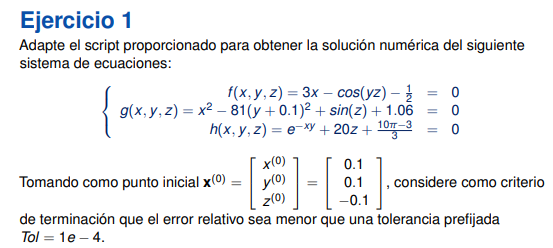

syms x y z                                                 % Declara x, y, z como variables simbólicas

F = @(x,y,z) [3*x-cos(y*z)-1/2; ...                       % Define la primera ecuación del sistema
    x^2-81*(y+0.1)^2+sin(z)+1.06; ...           % Define la segunda ecuación del sistema
    exp(-x*y)+20*z+(10*pi-3)/3];                % Define la tercera ecuación del sistema

dF = jacobian(F(x,y,z),[x,y,z]);                           % Calcula simbólicamente la matriz Jacobiana

dFfun = matlabFunction(dF,'Vars',{x,y,z});                 % Convierte la Jacobiana en una función numérica

x0 = [0.1; 0.1; -0.1];                                    % Define el punto inicial o punto semilla

Tol = 1e-4;                                                % Define la tolerancia del criterio de parada

dr = 1;                                                    % Inicializa el error relativo

i = 0;                                                     % Inicializa el contador de iteraciones

Z = [i x0' dr];                                            % Guarda la iteración inicial, el vector y el error

while dr > Tol                                             % Repite mientras el error sea mayor que la tolerancia

    dFfun_eval = dFfun(x0(1),x0(2),x0(3));                % Evalúa la Jacobiana en el punto actual

    x1 = x0 - inv(dFfun_eval)*F(x0(1),x0(2),x0(3));       % Calcula la siguiente aproximación mediante Newton

    dr = norm(x1-x0,'inf')/norm(x1,'inf');                % Calcula el error relativo con norma infinito

    x0 = x1;                                               % Actualiza el vector para la siguiente iteración

    i = i + 1;                                             % Incrementa el contador de iteraciones

    Z = [Z; i x1' dr];                                     % Guarda la nueva iteración y el error

end                                                        % Finaliza el ciclo

disp('   i          x             y             z            error') % Muestra encabezado

   i          x             y             z            error



disp(Z)                                                    % Muestra la tabla completa de iteraciones

         0    0.1000    0.1000   -0.1000    1.0000
    1.0000    0.4999    0.0195   -0.5215    0.8083
    2.0000    0.5000    0.0016   -0.5236    0.0341
    3.0000    0.5000    0.0000   -0.5236    0.0030
    4.0000    0.5000    0.0000   -0.5236    0.0000



cambio


syms x y z                                                 % Declara x, y, z como variables simbólicas

F = @(x,y,z) [3*x-cos(y*z)-1/2; ...                       % Define la primera ecuación
              x^2-81*(y+0.1)^2+sin(z)+1.06; ...           % Define la segunda ecuación
              exp(-x*y)+20*z+(10*pi-3)/3];                % Define la tercera ecuación

dF = jacobian(F(x,y,z),[x y z]);                           % Calcula simbólicamente la matriz Jacobiana

dFfun = matlabFunction(dF,'Vars',{x,y,z});                 % Convierte la Jacobiana en función numérica

x0 = [0.1; 0.1; -0.1];                                    % Define el punto inicial o semilla

Tol = 1e-4;                                                % Define la tolerancia

dr = 1;                                                    % Inicializa el error relativo

i = 0;                                                     % Inicializa el contador de iteraciones

Z = [i x0' dr];                                            % Guarda la iteración inicial

while dr > Tol                                             % Repite mientras el error sea mayor que la tolerancia

    dFfun_eval = dFfun(x0(1),x0(2),x0(3));                % Evalúa la Jacobiana en el punto actual %importante

    Ffun_eval = F(x0(1),x0(2),x0(3));                     % Evalúa el sistema F en el punto actual %importante

    x1 = x0 - inv(dFfun_eval)*Ffun_eval;                   % Calcula la nueva aproximación por Newton  %importante

    dr = norm(x1-x0,'inf')/norm(x1,'inf');                % Calcula el error relativo con norma infinito

    x0 = x1;                                               % Actualiza el punto para la siguiente iteración

    i = i + 1;                                             % Incrementa el contador de iteraciones

    Z = [Z; i x1' dr];                                     % Guarda la nueva iteración y su error

end                                                        % Finaliza el ciclo while

fprintf('\n')                                              % Deja una línea en blanco

fprintf(' i          x          y          z              error\n') % Imprime encabezado

 i          x          y          z              error



for j = 1:size(Z,1)                                        % Recorre todas las iteraciones almacenadas

    fprintf('%2.0f    %9.6f   %9.6f   %9.6f    %12.6e\n', ... % Define el formato de salida
        Z(j,1),Z(j,2),Z(j,3),Z(j,4),Z(j,5))                % Imprime iteración, x, y, z y error por ejemplo muestra 9 espacios 6 decimales

end                                                        % Finaliza el ciclo de impresión

 0     0.100000    0.100000   -0.100000    1.000000e+00
 1     0.499870    0.019467   -0.521520    8.082530e-01
 2     0.500014    0.001589   -0.523557    3.414768e-02
 3     0.500000    0.000012   -0.523598    3.010220e-03
 4     0.500000    0.000000   -0.523599    2.376630e-05


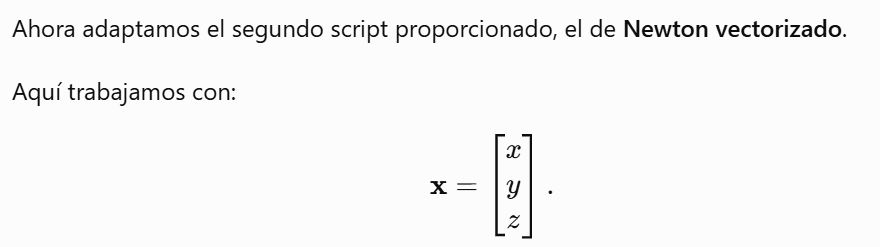

syms x [3 1]                                               % Crea un vector simbólico x de tres componentes

F = @(x) [3*x(1)-cos(x(2)*x(3))-1/2; ...                  % Define la primera ecuación
    x(1)^2-81*(x(2)+0.1)^2+sin(x(3))+1.06; ...      % Define la segunda ecuación
    exp(-x(1)*x(2))+20*x(3)+(10*pi-3)/3];           % Define la tercera ecuación

J_sym = jacobian(F(x),x);                                  % Calcula la Jacobiana simbólica del sistema

J = matlabFunction(J_sym,'Vars',{x});                      % Convierte la Jacobiana en función numérica vectorizada

x0 = [0.1; 0.1; -0.1];                                    % Define el vector inicial

Tol = 1e-4;                                                % Define la tolerancia

error = 1;                                                 % Inicializa el error relativo

i = 0;                                                     % Inicializa el contador de iteraciones

Z = [i x0' error];                                         % Guarda los valores iniciales

while error > Tol                                          % Ejecuta mientras el error sea mayor que la tolerancia

    x1 = x0 - inv(J(x0))*F(x0);                            % Calcula la nueva aproximación mediante Newton

    error = norm(x1-x0,'inf')/norm(x1,'inf');             % Calcula el error relativo usando norma infinito

    x0 = x1;                                               % Actualiza el vector

    i = i + 1;                                             % Incrementa el número de iteración

    Z = [Z; i x1' error];                                  % Guarda los resultados de la iteración

end                                                        % Finaliza el ciclo

disp('   i          x             y             z            error') % Muestra encabezado

   i          x             y             z            error



disp(Z)                                                    % Muestra todas las iteraciones

         0    0.1000    0.1000   -0.1000    1.0000
    1.0000    0.4999    0.0195   -0.5215    0.8083
    2.0000    0.5000    0.0016   -0.5236    0.0341
    3.0000    0.5000    0.0000   -0.5236    0.0030
    4.0000    0.5000    0.0000   -0.5236    0.0000



cambiamos la parte final 

clear; clc;                                                % Limpia las variables y la ventana de comandos

F = @(x) [3*x(1)-cos(x(2)*x(3))-1/2; ...                  % Define la primera ecuación
    x(1)^2-81*(x(2)+0.1)^2+sin(x(3))+1.06; ...      % Define la segunda ecuación
    exp(-x(1)*x(2))+20*x(3)+(10*pi-3)/3];           % Define la tercera ecuación

x0 = [0.1; 0.1; -0.1];                                    % Define el vector inicial o semilla

n = length(x0);                                            % Determina el número de variables del sistema

syms x [n 1]                                               % Crea un vector simbólico de n componentes

J_sym = jacobian(F(x),x);                                  % Calcula simbólicamente la matriz Jacobiana

J = matlabFunction(J_sym,'Vars',{x});                      % Convierte la Jacobiana en función numérica

Tol = 1e-4;                                                % Define la tolerancia

error = 1;                                                 % Inicializa el error relativo

i = 0;                                                     % Inicializa el contador de iteraciones

Z = [i x0' error];                                         % Guarda el punto inicial y el error

while error > Tol                                          % Repite mientras no se alcance la tolerancia

    J_eval = J(x0);                                        % Evalúa la Jacobiana en el vector actual

    F_eval = F(x0);                                        % Evalúa el sistema en el vector actual

    x1 = x0 - inv(J_eval)*F_eval;                          % Aplica la fórmula vectorizada de Newton

    error = norm(x1-x0,'inf')/norm(x1,'inf');             % Calcula el error relativo con norma infinito

    x0 = x1;                                               % Actualiza el vector para la siguiente iteración

    i = i + 1;                                             % Incrementa el contador de iteraciones

    Z = [Z; i x1' error];                                  % Guarda la iteración y el error

end                                                        % Finaliza el ciclo while

fprintf('\n')                                              % Deja una línea en blanco

fprintf(' i          x          y          z              error\n') % Imprime encabezado

 i          x          y          z              error



for j = 1:size(Z,1)                                        % Recorre todas las iteraciones almacenadas

    fprintf('%2.0f    %9.6f   %9.6f   %9.6f    %12.6e\n', ... % Define formato de impresión
        Z(j,1),Z(j,2),Z(j,3),Z(j,4),Z(j,5))                % Muestra los resultados

end                                                        % Finaliza el ciclo de impresión

 0     0.100000    0.100000   -0.100000    1.000000e+00
 1     0.499870    0.019467   -0.521520    8.082530e-01
 2     0.500014    0.001589   -0.523557    3.414768e-02
 3     0.500000    0.000012   -0.523598    3.010220e-03
 4     0.500000    0.000000   -0.523599    2.376630e-05
